
addpath myFunction\myftn\
clearvars -except Gfinal0T ImgFinalZnorm vm x y Zfinal0T
;close all;clc

fn = "RawData\1T-TaS2(point defect)\Gxy0T.mat"

fn = "RawData\1T-TaS2(point defect)\Gxy0T.mat"

loadif(fn)

fldNm = 6×1 cell array
    {'x'            }
    {'Gfinal0T'     }
    {'ImgFinalZnorm'}
    {'vm'           }
    {'Zfinal0T'     }
    {'y'            }



Your variables are:

fldNm  fn     mt     



ans = 'already'

margins = [700 770]

margins =    700   770


is_load_useful(fn)

fldNm = 6×1 cell array
    {'x'            }
    {'Gfinal0T'     }
    {'ImgFinalZnorm'}
    {'vm'           }
    {'Zfinal0T'     }
    {'y'            }



Your variables are:

fldNm  fn     mt     



ans = logical
   0


Visible on

gr  = groot();
gr.Units = "normalized";
mp = gr.MonitorPositions;
f1 = figure(1);
f1.Units  = "normalized";
f1.Position = secondNormalization(mp(1,:),[0 0 1 1]);
f1.Visible = "on";

subplotting

msb = 3

msb = 3

nsb = 5

nsb = 5

axReal = subplot(msb,nsb,1:10,'Tag','axReal');
axReal.Tag

ans = 'axReal'

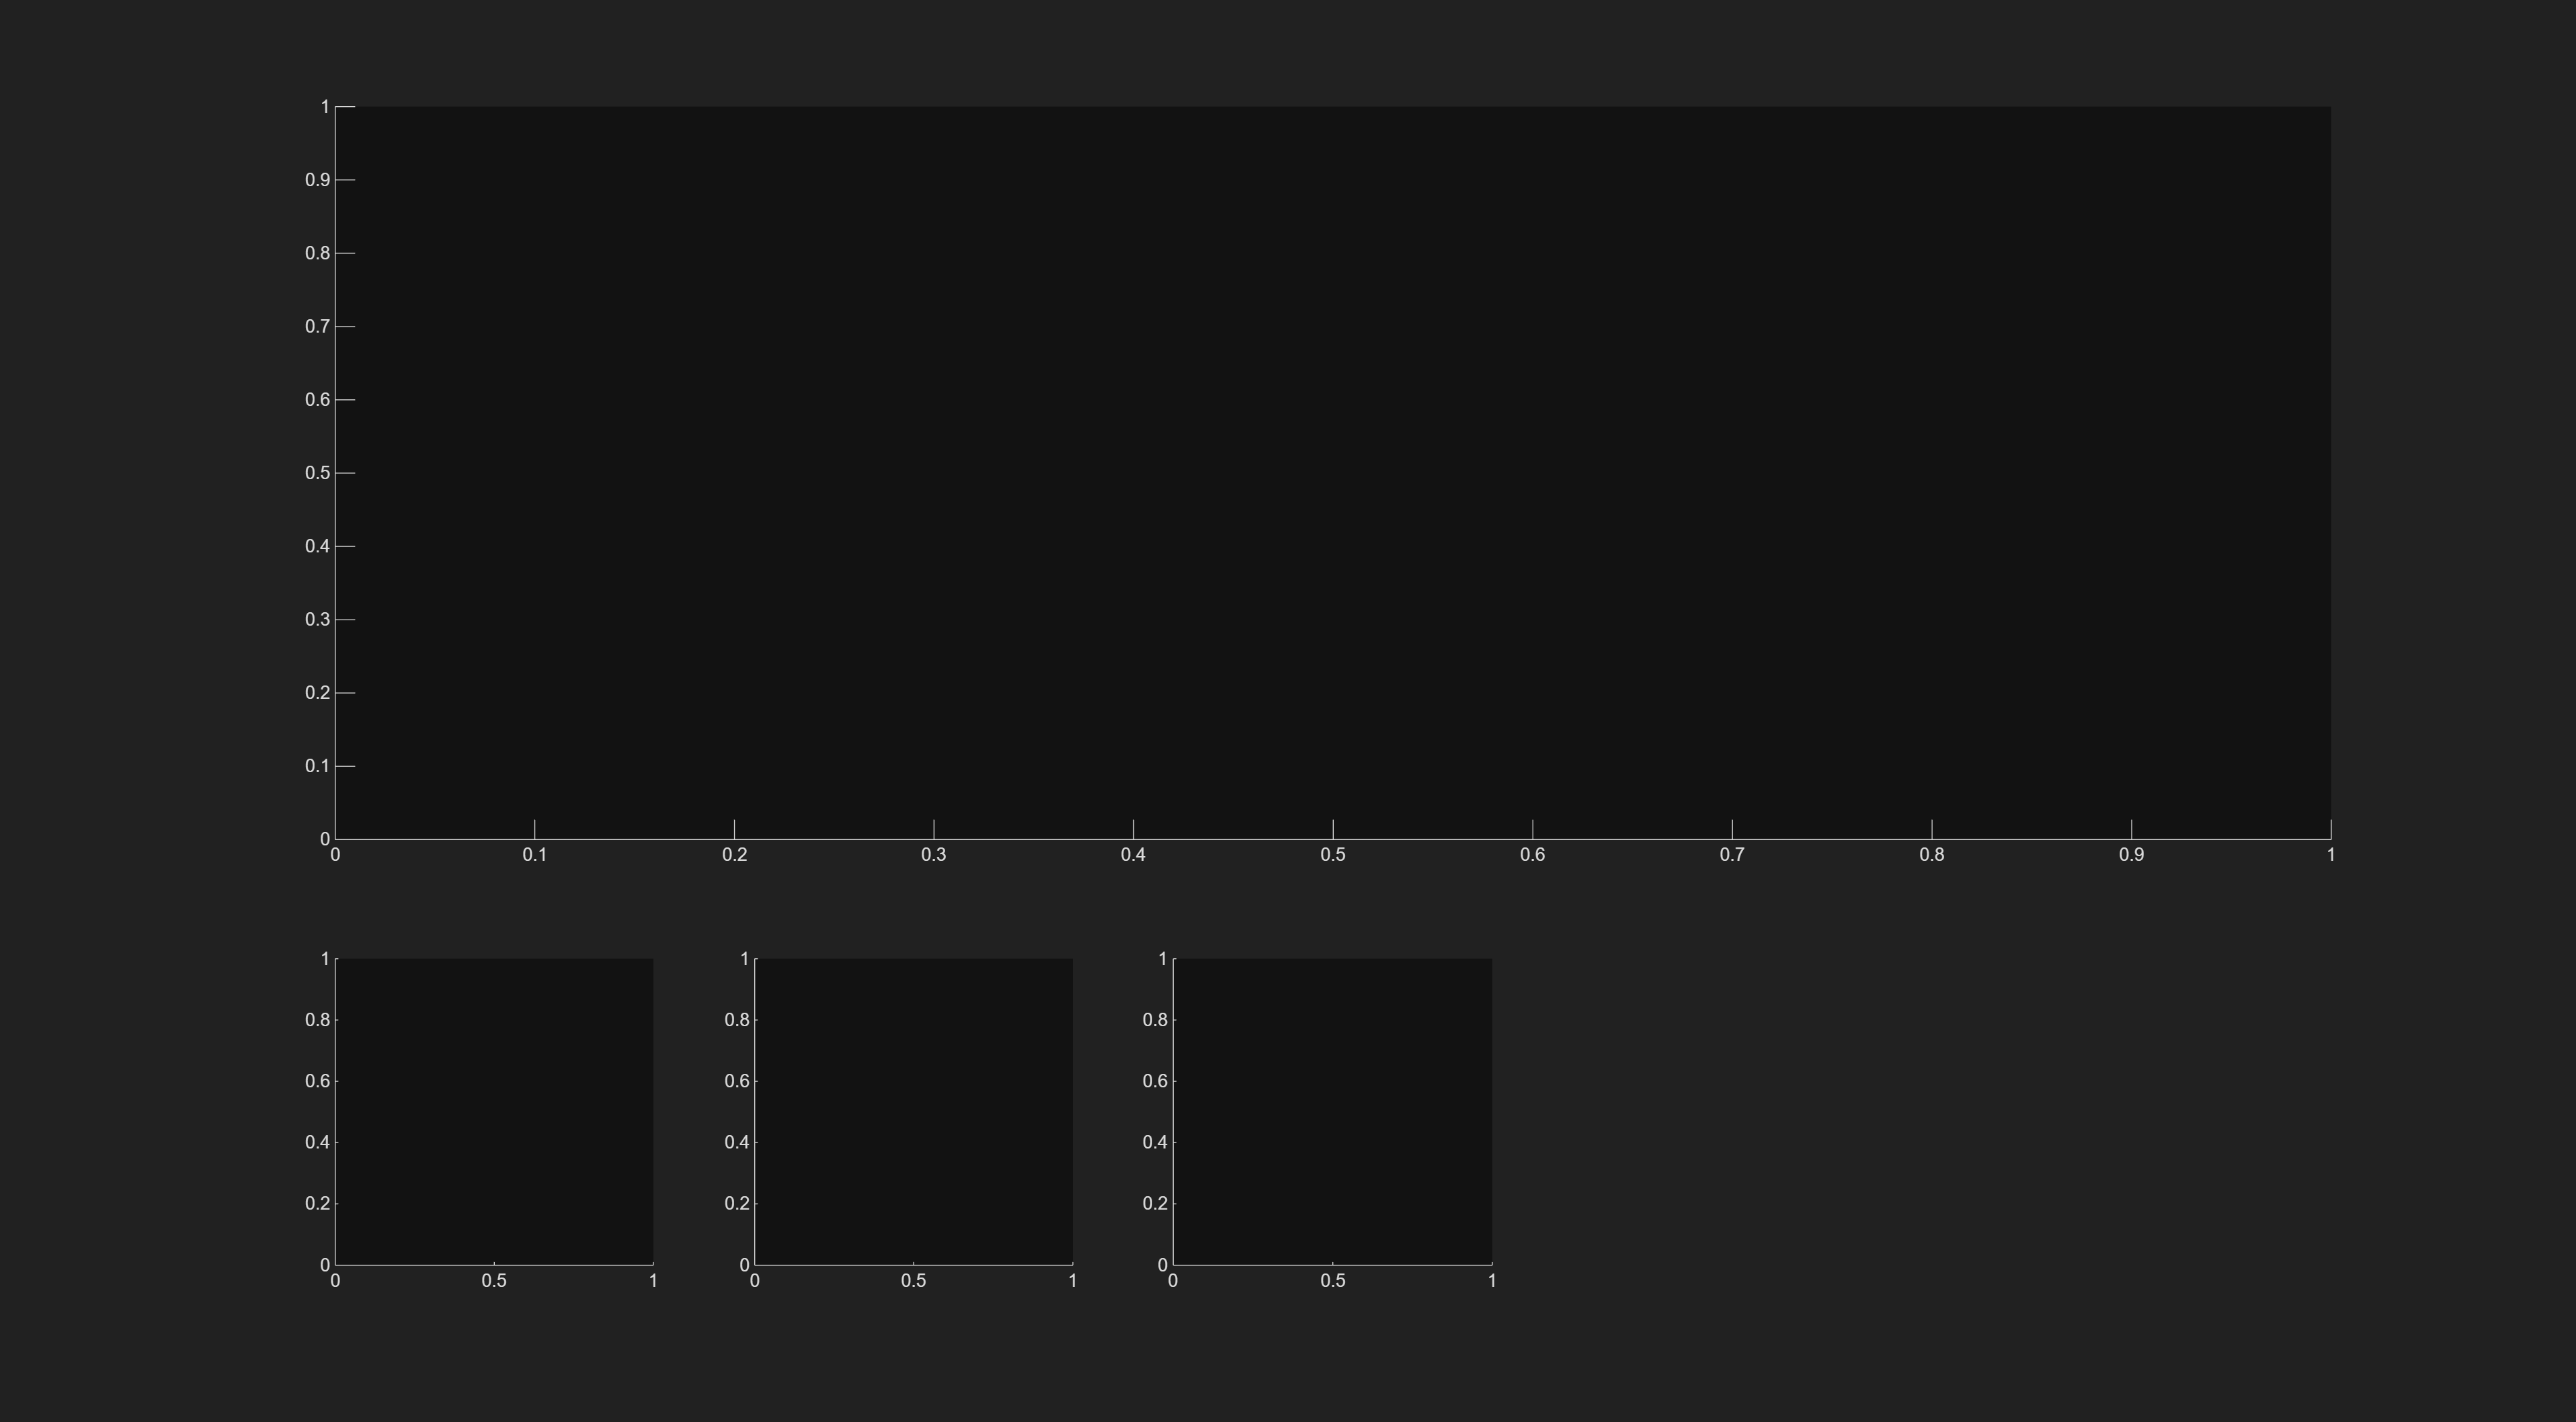

axDos = subplot(msb,nsb,11,'Tag','axDos');
axHis = subplot(msb,nsb,12,'Tag','axHis');
axZoom = subplot(msb,nsb,13,'Tag','axZoom');

rngs = [1 margins(1);margins(2) size(Gfinal0T,1)];

whichDm = 1

whichDm = 1

imgInfo = 2

imgInfo = 2

iv = 952%16

iv = 952

xpxl = 320

xpxl = 320

ypxl = 318

ypxl = 318

vNow = vm(iv)

vNow = 0.1910

결측치 처리

% sub_TrueData = ~Gfinal0T(:,:,100) == 0
% ind_TrueData = sub_TrueData(:);
% sz = size(Gfinal0T);
% szTemp = [sz(1)*sz(2),sz(3)];
% Gfinal0T = reshape(Gfinal0T,szTemp);
% Gfinal0T(ind_TrueData,:) = nan

DataProcessing(dependent on )

rng = rngs(whichDm,:);
G = Gfinal0T(rng(1):rng(2),:,:);%%%%% 속도 결정 단계
Z = ImgFinalZnorm(rng(1):rng(2),:,:);%
g_at = squeeze(G(xpxl,ypxl,:));
gavg = squeeze(mean(mean(G)));

## Graphic

### Initial Graphic Elements

Topography

f1.CurrentAxes = axReal

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [0.0027 1.2528 0.7484 0.7347]
       Units: 'normalized'

  Show all properties


axReal.Tag

ans = 'axReal'

imgRegion(G,Z,imgInfo,iv)

ans = 'before'

ans = 'axReal'

ans = 'after'

ans = 'axReal'

axReal.Tag

ans = 'axReal'

hold on
highlightPts(xpxl,ypxl)
hold off
axReal.Tag ='axReal'

axReal =   Axes (axReal) with properties:

             XLim: [0.5000 700.5000]
             YLim: [0.5000 729.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4096 0.7750 0.5154]
            Units: 'normalized'

  Show all properties


Zoomed Topography

f1.CurrentAxes = axZoom

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [0.0027 1.2528 0.7484 0.7347]
       Units: 'normalized'

  Show all properties


xrng = (-20:20) +xpxl;
yrng = (-20:20) + ypxl;
imgRegion(G(xrng,yrng,:),Z(xrng,yrng),imgInfo,iv)

ans = 'before'

ans = 'axZoom'

ans = 'after'

ans = 'axZoom'

Point STS

f1.CurrentAxes = axDos

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [0.0027 1.2528 0.7484 0.7347]
       Units: 'normalized'

  Show all properties


% V 
plot(vm,g_at,'Tag','g_at')
hold on
plot(vm,gavg,'Tag','gavg')
hold off
nowV = xline(vm(iv),'Tag','nowV');
xlim([-1 1]*.6)
legend(["point" "Averaged"])
xlabel('V (V)')
ylabel('Averaged LDOS (Arb)')

Histogram at specific Energy

f1.CurrentAxes = axHis

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [0.0027 1.2528 0.7484 0.7347]
       Units: 'normalized'

  Show all properties


conductanceMap = G(:,:,iv);
conductanceMap = conductanceMap(:);
conductanceMap = conductanceMap(~conductanceMap==0);
histogram(conductanceMap)
xline(g_at(iv),'Tag','nowDos')
% min(conductanceMap)
% max(conductanceMap)
xlabel('LDOS')
ylabel('LDOS')
axHis.Tag = 'axHis'

axHis =   Axes (axHis) with properties:

             XLim: [-0.0411 0.7971]
             YLim: [0 35000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.2928 0.1100 0.1237 0.2157]
            Units: 'normalized'

  Show all properties


Change Pts in GUI

setappdata(f1,'is_dragging',false)
setappdata(f1,'drag_object',[])
setappdata(f1,'iv',iv)
set(axReal.Children(2), 'ButtonDownFcn', @(src,event) changePts(src,event,G,Z,imgInfo,iv));
set(nowV,'ButtonDownFcn',@(src,event) start_drag(src,event))
set(f1,'WindowButtonUpFcn',@(src,event) stop_drag(src,event))
set(f1, 'WindowButtonMotionFcn',@(src,event) draging(src,event,vm,G,Z,imgInfo))
% set(f1,'WindowButtonUpFcn',@(src,event) stop_drag(src,event))

Change Pts in GUI

% function changeE(src,event)
% src
% event
% end
% set(axDos, 'ButtonDownFcn', @changeE);

axReal.Tag

ans = 'axReal'

axHis.Tag

ans = 'axHis'

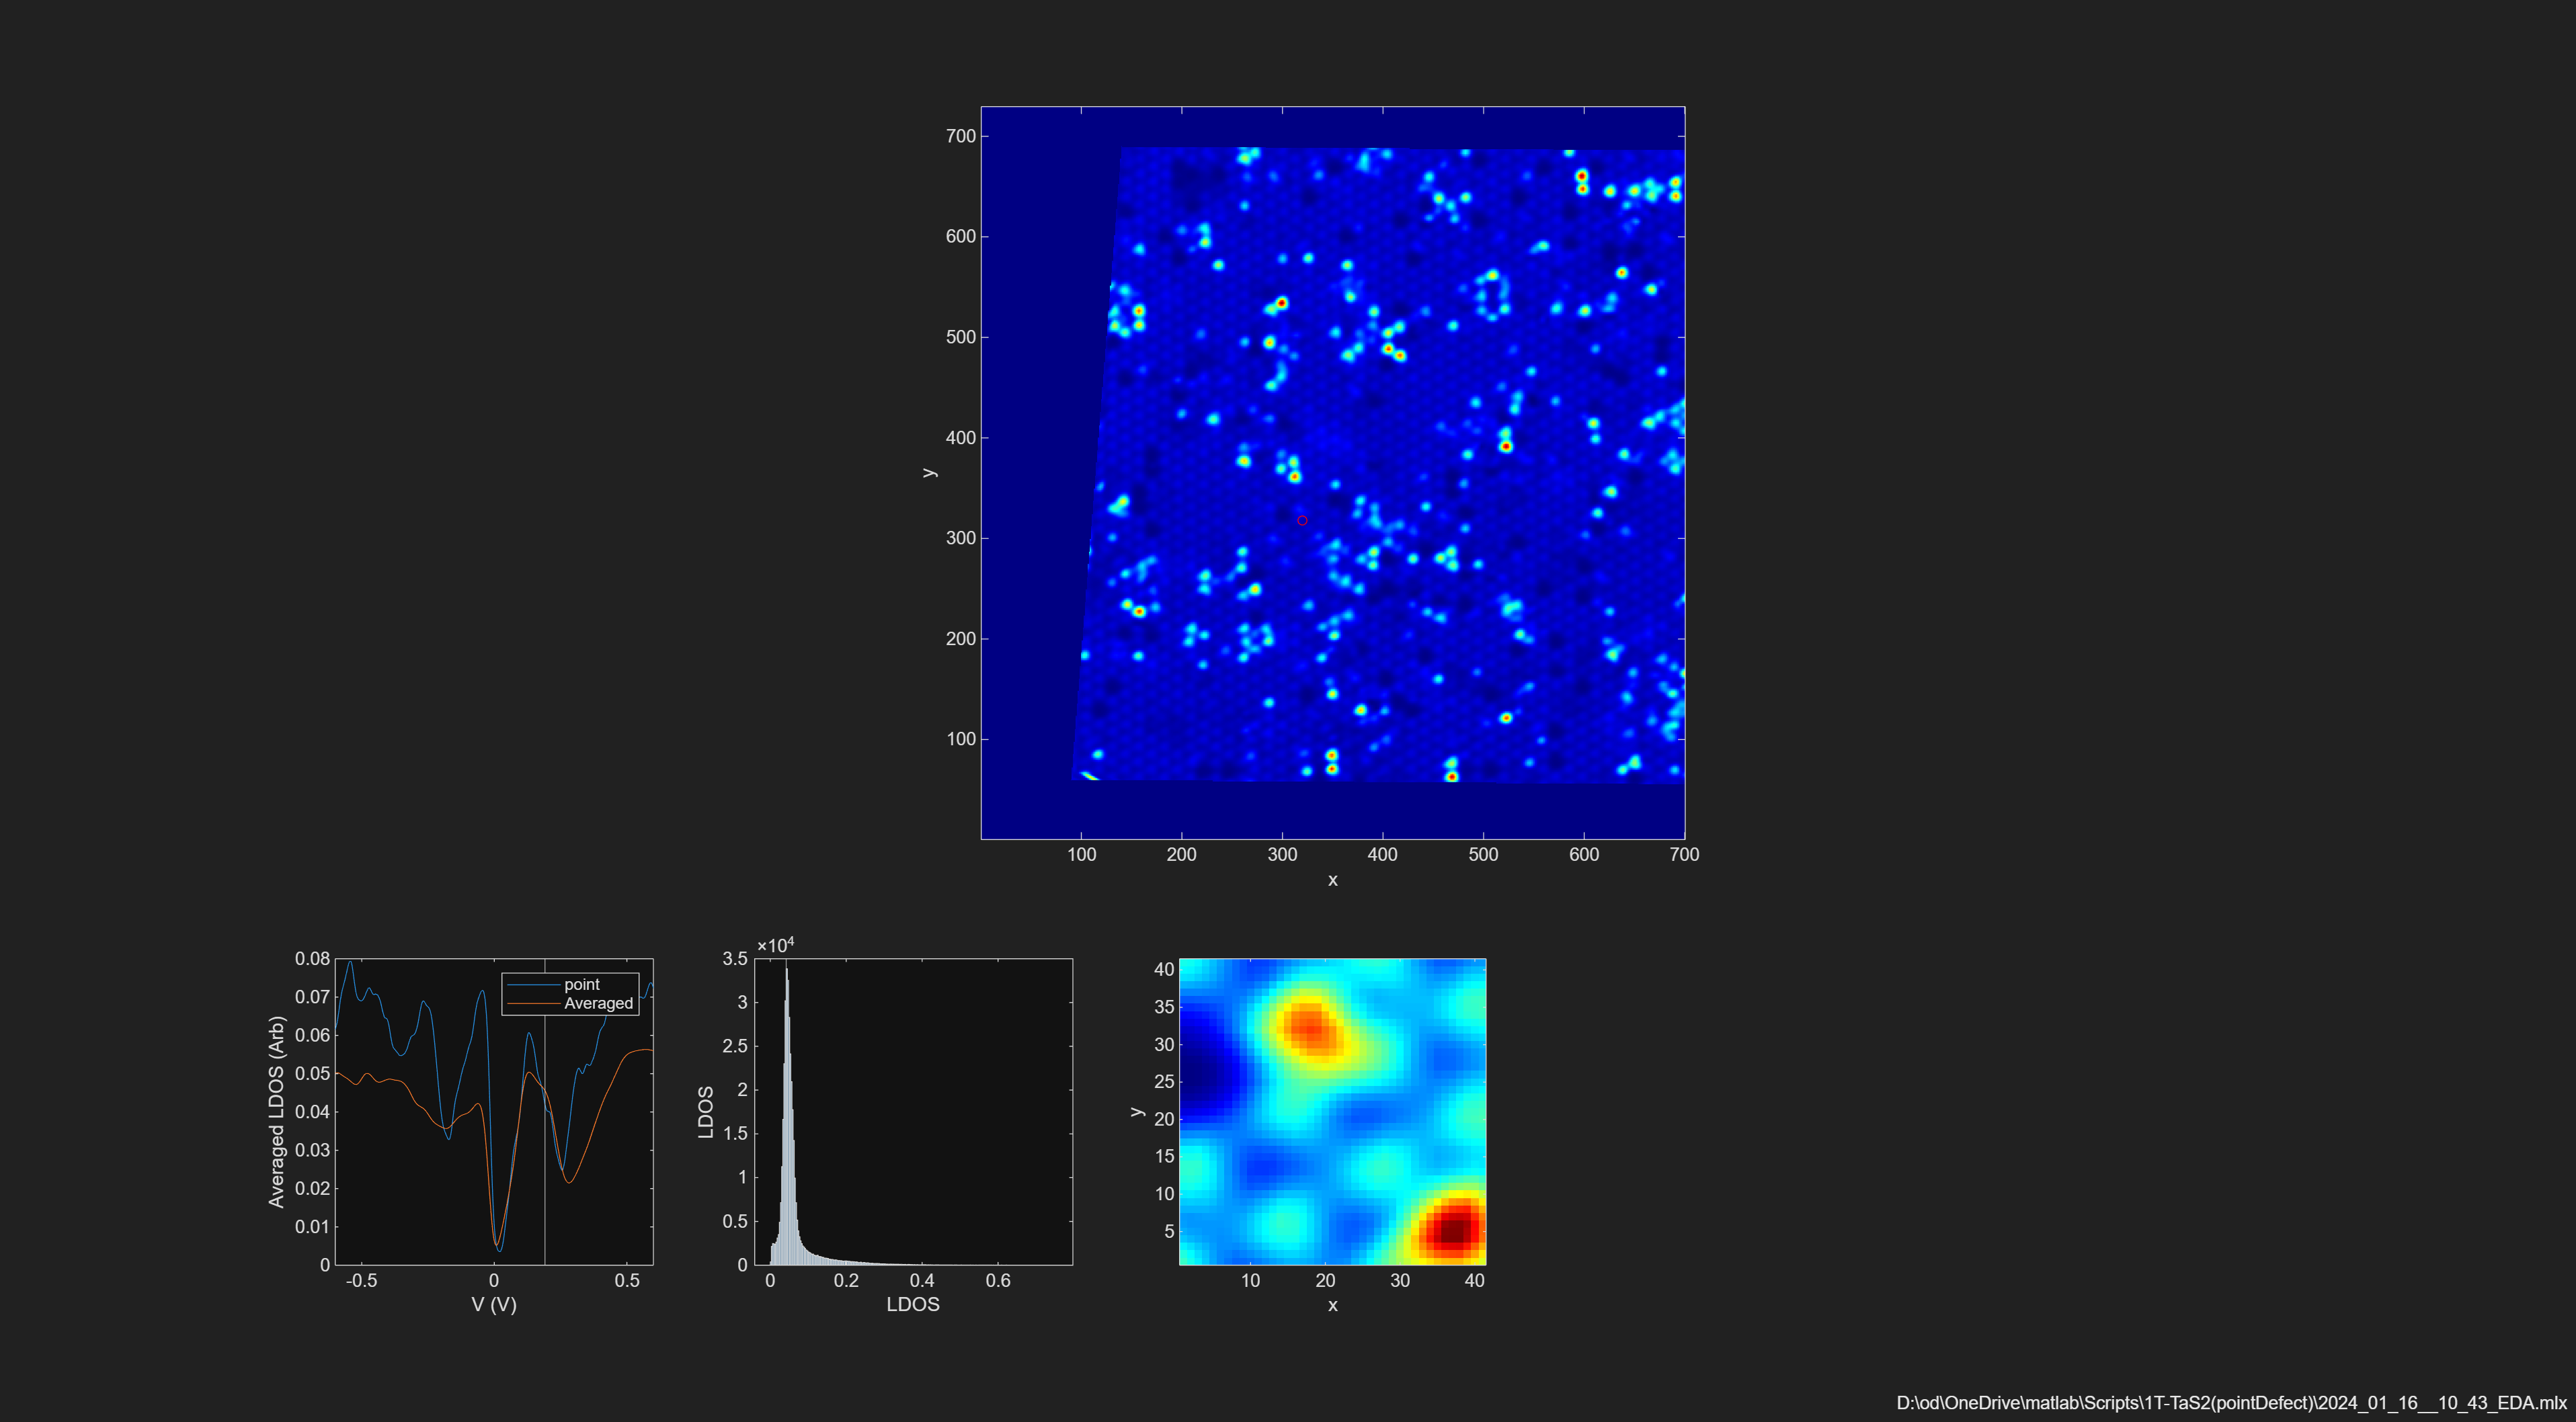

waterMark()

function changePts(src,event,G,Z,imgInfo,iv)
% src
% event
pts = round(event.IntersectionPoint);

%change red point 
gobj = findobj('Tag','highlightPts');
gobj.XData = pts(1);
gobj.YData = pts(2);

%change point ldos
g_at = squeeze(G(pts(1),pts(2),:));
gobj = findobj('Tag','g_at');
gobj.YData = g_at';


%change zoom
f1 = gcf;
f1.CurrentAxes = findobj('Tag','axZoom');
xrng = (-20:20) + pts(1);
yrng = (-20:20) + pts(2);
imgRegion(G(xrng,yrng,:),Z(xrng,yrng),imgInfo,iv);

%Change His
f1 = gcf;
% ax= findobj(f1,'Tag','axHis');
% const_line = findobj()
nowDos = findobj(f1,'Tag','nowDos');
iv = getappdata(f1,'iv');
nowDos.Value = g_at(iv)
end

function imgRegion(G,Z,imgInfo,iv)
ax = gca;
'before'
ax.Tag
axTag = ax.Tag;
if imgInfo == 1
    imgfoo = Z;
elseif imgInfo == 2
    imgfoo = G(:,:,iv);
end

imagesc(imgfoo');
axis image;
'after'
ax.Tag = axTag;
ax.Tag
ax.YDir = 'normal';

xlabel('x');
ylabel('y');
if imgInfo == 1
    colormap gray;



elseif imgInfo == 2
    colormap jet;
end

% hold on
% plot(xpxl,ypxl,'ro','MarkerSize',5)
end

function highlightPts(xpxl,ypxl)
plot(xpxl,ypxl,'ro','MarkerSize',5,'Tag','highlightPts')
end

function start_drag(src,event)
%src
%event
disp('start')
setappdata(gcf,'drag_object',src)
% disp(src.Value)
% disp(getappdata(gcf,'drag_object'))
end


function stop_drag(src,event)
disp('stop')
setappdata(gcf,'drag_object',[])
%src
%event
end

function draging(src,event,vm,G,Z,imgInfo)

% getappdata(src,'drag_object')
if ~isempty(getappdata(src,'drag_object'))
    drag_object = getappdata(src,'drag_object')
    if isequal(drag_object.Tag,'nowV') %case of Bias Change
        cp = drag_object.Parent.CurrentPoint;
        drag_object.Value =  cp(1);

        [~,iv] = min(abs(vm - cp(1)))% change corresponding image
        ax = findobj('Tag','axReal');        
        img = findobj(ax,'Type','image');
        Gat = (G(:,:,iv))';
        img.CData = Gat;
        setappdata(src,'iv',iv)
        % ax = findobj('Tag','axHis');
        his = findobj(src,'Type','Histogram')
        Gat = Gat(:);
        Gat = Gat(~Gat==0);
        his.Data = Gat;
        
    end
    % drag_object.Value =  cp(1);
    % disp('stop')
    %src
    %event
    % if getappdata(src,)
end
end

% handlingMi
function G_new =  zero2nan(G)
G_new = G;
isZeroThick = G == 0;
nPage = size(G,3);
isZeroThin = all(isZeroThick,3);
isZeroThinRep = repmat(isZeroThin,[1 1 nPage]);
G_new(isZeroThinRep) = nan;
end